%Important to note that this program takes a fair amount of time to finish.
%As 24 FEAs are being performed and 3 finer meshes are created.
%It takes about 2-5 mins to run

%Section 1 (Variable initialization)
load("droneArmMaterials.mat")

%To get information from file do: materials(i).(TopRowName)
%Ex. materials(1).name will give Carbon Fiber Composite (CFRP)
Max_mats = length(materials); %Used for amount of loop runs
MaxThrust = 4; %(kg)
DroneWeightAllowed = MaxThrust/2; %(kg) To ensure the 2:1 T/W ratio is followed
MinPayLoad = 0.5; %(kg) Min req for payload
DroneComps = 1; %(kg) Weight of other drone components

%Variables to hold and display masses later
DroneArm1 = zeros(1,Max_mats)'; %(kg)
PayloadMax1 = zeros(1,Max_mats)'; %(kg)

DroneArm2 = zeros(1,Max_mats)'; %(kg)
PayloadMax2 = zeros(1,Max_mats)'; %(kg)

DroneArm3 = zeros(1,Max_mats)'; %(kg)
PayloadMax3 = zeros(1,Max_mats)'; %(kg)

DroneArm4 = zeros(1,Max_mats)'; %(kg)
PayloadMax4 = zeros(1,Max_mats)'; %(kg)


%Importing of models. Matlab always assumes ms when handling models. Scale
%function is there to allow for proper FEA and calcs. 
%models are in mm except 2

%For the best experience for importing models please use SolidWorks
gm1 = importGeometry("Triangle_ArmMod.STL"); 
gm2 = importGeometry("Circle_Arm.STL"); %model in m already
gm3 = importGeometry("Beam_Arm.STL");
gm4 = importGeometry("Lattice_ArmV2.STL");


gm1 = scale(gm1, 1E-3);
%scale(gm2, 1E-3);
gm3 = scale(gm3, 1E-3);
gm4 = scale(gm4, 1E-3);


md1 = femodel(AnalysisType="structuralStatic", Geometry = gm1); 
md2 = femodel(AnalysisType="structuralStatic", Geometry = gm2);
md3 = femodel(AnalysisType="structuralStatic", Geometry = gm3);
md4 = femodel(AnalysisType="structuralStatic", Geometry = gm4); 

%No longer needed. Can be accessed through mds
clearvars gm1 gm2 gm3 gm4

%model 2 required are coarser mesh
%model 3 required a finer one compared to the others.
md1 = generateMesh(md1, Hmin=.0005, Hmax=1);
md2 = generateMesh(md2);
md3 = generateMesh(md3, Hmin=.00005, Hmax=1);
md4 = generateMesh(md4, Hmin=.0005, Hmax=1);

%Section 2 (For devs)

%This section is for other programmers adapting the code for their models.
%These pde functions are here to allow you to quickly run this section to
%see where the faces are for the model

 %figure
%pdemesh(md1);
% %figure
%pdemesh(md2);
% %figure
% pdemesh(md3);
% 
%  pdemesh(md4);
% 
% 
 % figure
 % pdegplot(md1,FaceLabels="on", FaceAlpha=.3);
 % figure
 % pdegplot(md1,FaceLabels="on", FaceAlpha=1);
% 
 %  figure
 %  pdegplot(md2,FaceLabels="on", FaceAlpha=0.3);
 %  figure
 % pdegplot(md2,FaceLabels="on", FaceAlpha=1);
% 
% figure
%  pdegplot(md3,FaceLabels="on", FaceAlpha=0.3);
%  figure
%  pdegplot(md3,FaceLabels="on", FaceAlpha=1);
%  figure
% pdegplot(md3,FaceLabels="off", FaceAlpha=1);
% 
 % figure
 % pdegplot(md4,FaceLabels="on", FaceAlpha=0.3);
 % figure
 % pdegplot(md4,FaceLabels="on", FaceAlpha=1);
 % 



%Section 3 (Thrust to weight analysis occurs here)

names = strings(1,Max_mats)'; %Holds names of materials in a vector col for more convenient use later.

%Vol variables are created to calculate weights and costs of the drone arms
%Vol#c is created with the assumption that the material will be cut from a
%block of material. Thus using more actual material than the volume command
%of the mesh states. 
% The 2 separate cost variables are the result of the
%confusion in regards to how much materials costs. cost# assumes the
%materials cost column is in ($/m) while cost#g assumes it to be ($/Kg)

%The vol#c calc assumes the models are aligned with the origin point and
%take up space in the positive direction.
vol1=volume(md1.Geometry.Mesh); 
vol1c = max(md1.Geometry.Vertices(:,1))*max(md1.Geometry.Vertices(:,2))*max(md1.Geometry.Vertices(:,3));
cost1 = zeros(1,Max_mats)';
cost1g = zeros(1,Max_mats)';

%Model 2 was made in a different program. So, it's vol2c was hand calculated.
vol2=volume(md2.Geometry.Mesh); 
vol2c = 2.252E-5;
cost2 = zeros(1,Max_mats)';
cost2g = zeros(1,Max_mats)';

vol3=volume(md3.Geometry.Mesh); 
vol3c = max(md3.Geometry.Vertices(:,1))*max(md3.Geometry.Vertices(:,2))*max(md3.Geometry.Vertices(:,3));
cost3 = zeros(1,Max_mats)';
cost3g = zeros(1,Max_mats)';

vol4=volume(md4.Geometry.Mesh); 
vol4c = max(md4.Geometry.Vertices(:,1))*max(md4.Geometry.Vertices(:,2))*max(md4.Geometry.Vertices(:,3));
cost4 = zeros(1,Max_mats)';
cost4g = zeros(1,Max_mats)';

%Calc for drone arm weights, max payload, and costs
%This is also where the Thrust to Weight ratio (TWR) analysis occurs. 
%Since the TWR is locked at 2 from the variable setup in section 1 to
%ensure the heaviest payload possible.

for i = 1:Max_mats
    names(i) = materials(i).name;
    DroneArm1(i) = vol1 * materials(i).rho_kg_m3;
    PayloadMax1(i) = DroneWeightAllowed - DroneArm1(i)*4 - DroneComps; %This calc ensures a 2:1 TWR
    cost1(i) = vol1 * (materials(i).cost_USD_per_m^3);
    cost1g(i) = vol1c * materials(i).rho_kg_m3 * materials(i).cost_USD_per_m;

    DroneArm2(i) = vol2 * materials(i).rho_kg_m3;
    PayloadMax2(i) = DroneWeightAllowed - DroneArm2(i)*4 - DroneComps;
    cost2(i) = vol2c * (materials(i).cost_USD_per_m)^3;
    cost2g(i) = vol2c * materials(i).rho_kg_m3* materials(i).cost_USD_per_m;

    DroneArm3(i) = vol3 * materials(i).rho_kg_m3;
    PayloadMax3(i) = DroneWeightAllowed - DroneArm3(i)*4 - DroneComps;
    cost3(i) = vol3c * (materials(i).cost_USD_per_m)^3;
    cost3g(i) = vol3c * materials(i).rho_kg_m3* materials(i).cost_USD_per_m;

    DroneArm4(i) = vol4 * materials(i).rho_kg_m3;
    PayloadMax4(i) = DroneWeightAllowed - DroneArm4(i)*4 - DroneComps;
    cost4(i) = vol4c * (materials(i).cost_USD_per_m^3);
    cost4g(i) = vol4c * materials(i).rho_kg_m3* materials(i).cost_USD_per_m;

end



%Section 4 (Applying locking faces and loading forces)

%This section is where the restraints and loads are placed on the model
%Viewing the models will show that some of the models are orientated
%differently. Which is why the loads are either applied on the y or z axis

%9.07 is the force that area of the arm faces. 
% 9.8 - (9.8 * motor weight(65g)* propeller weight(10g)) = 9.065N
%It was then rounded up to 9.07N.
%It is then divided by the surface area of the face it is attached to (2*pi*r*depth)
%Which makes the results give an approximation for FEAs
%Lastly sanity checks were done hand calced and using SolidWorks as a
%reference for results.

md1.FaceBC([63,64,65,66]) = faceBC(Constraint="fixed");
md1.FaceLoad(58) = faceLoad(SurfaceTraction= [0;0;9.07/(2*pi*7.5*6*1e-6)]);
md1.CellLoad = cellLoad(Gravity=[0 0 -9.8]);

md2.FaceBC([12]) = faceBC(Constraint="fixed");
md2.FaceLoad(11) = faceLoad(SurfaceTraction= [0; 9.07/(2*pi*3.5*5*1e-6); 0]);
md2.CellLoad = cellLoad(Gravity=[0, -9.8, 0]);

md3.FaceBC([12,13,14,15]) = faceBC(Constraint="fixed");
md3.FaceLoad(11) = faceLoad(SurfaceTraction= [0;0;9.07/(2*pi*1.5*4.8*1e-6)]);
md3.CellLoad = cellLoad(Gravity=[0 0 -9.8]);

md4.FaceBC([3,24,25,34]) = faceBC(Constraint="fixed");
md4.FaceLoad(26) = faceLoad(SurfaceTraction= [0;9.07/(2*pi*2.65*1.9*1e-6);0]);
md4.CellLoad = cellLoad(Gravity=[0 -9.8 0]);

%Section 5 (FEA calcs)

%Pass this point are 4 big sections of code where FEA is performed on the 4
%drone arms. They are handled via switch case. Separate variables are used
%to store the FEA results in order for the built in "Visualize PDE Results"
%to allow the results to be selectable and viewable.

%Explanation comments return after this section

%Model 1
Max_Stress1 = zeros(1,6)';
Max_Disp1 = zeros(1,6)';
FoS1 = zeros(1,6)';
for i = 1:Max_mats 

    md1.MaterialProperties = ...
        materialProperties(YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);
    
    switch i
        case 1
            Model_1_result_CFRP = solve(md1);
            Max_Stress1(i) = max(Model_1_result_CFRP.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_CFRP.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 2
            Model_1_result_Al_Alloy = solve(md1);
            Max_Stress1(i) = max(Model_1_result_Al_Alloy.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_Al_Alloy.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 3
            Model_1_result_GFRP = solve(md1);
            Max_Stress1(i) = max( Model_1_result_GFRP.VonMisesStress);
            Max_Disp1(i) = max( Model_1_result_GFRP.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 4
            Model_1_result_PLA = solve(md1);
            Max_Stress1(i) = max(Model_1_result_PLA.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_PLA.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 5
            Model_1_result_ASB = solve(md1);
            Max_Stress1(i) = max(Model_1_result_ASB.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_ASB.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
        case 6
            Model_1_result_Wood = solve(md1);
            Max_Stress1(i) = max(Model_1_result_Wood.VonMisesStress);
            Max_Disp1(i) = max(Model_1_result_Wood.Displacement.Magnitude);
            FoS1(i) = materials(i).yieldStrength_Pa / Max_Stress1(i);
   
    end


end



%For model 2
Max_Stress2 = zeros(1,6)';
Max_Disp2 = zeros(1,6)';
FoS2 = zeros(1,6)';
for i = 1:Max_mats 

    md2.MaterialProperties = ...
        materialProperties(YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);

    switch i
        case 1
            Model_2_result_CFRP = solve(md2);
            Max_Stress2(i) = max(Model_2_result_CFRP.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_CFRP.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 2
            Model_2_result_Al_Alloy = solve(md2);
            Max_Stress2(i) = max(Model_2_result_Al_Alloy.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_Al_Alloy.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 3
            Model_2_result_GFRP = solve(md2);
            Max_Stress2(i) = max( Model_2_result_GFRP.VonMisesStress);
            Max_Disp2(i) = max( Model_2_result_GFRP.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 4
            Model_2_result_PLA = solve(md2);
            Max_Stress2(i) = max(Model_2_result_PLA.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_PLA.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 5
            Model_2_result_ASB = solve(md2);
            Max_Stress2(i) = max(Model_2_result_ASB.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_ASB.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);
        case 6
            Model_2_result_Wood = solve(md2);
            Max_Stress2(i) = max(Model_2_result_Wood.VonMisesStress);
            Max_Disp2(i) = max(Model_2_result_Wood.Displacement.Magnitude);
            FoS2(i) = materials(i).yieldStrength_Pa / Max_Stress2(i);

    end


end

%For model 3

Max_Stress3 = zeros(1,6)';
Max_Disp3 = zeros(1,6)';
FoS3 = zeros(1,6)';
for i = 1:Max_mats 

    md3.MaterialProperties = ...
        materialProperties(YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);
    
    switch i
        case 1
            Model_3_result_CFRP = solve(md3);
            Max_Stress3(i) = max(Model_3_result_CFRP.VonMisesStress);
            Max_Disp3(i) = max(Model_3_result_CFRP.Displacement.Magnitude);
            FoS3(i) = materials(i).yieldStrength_Pa / Max_Stress3(i);
        case 2
            Model_3_result_Al_Alloy = solve(md3);
            Max_Stress3(i) = max(Model_3_result_Al_Alloy.VonMisesStress);
            Max_Disp3(i) = max(Model_3_result_Al_Alloy.Displacement.Magnitude);
            FoS3(i) = materials(i).yieldStrength_Pa / Max_Stress3(i);
        case 3
            Model_3_result_GFRP = solve(md3);
            Max_Stress3(i) = max( Model_3_result_GFRP.VonMisesStress);
            Max_Disp3(i) = max( Model_3_result_GFRP.Displacement.Magnitude);
            FoS3(i) = materials(i).yieldStrength_Pa / Max_Stress3(i);
        case 4
            Model_3_result_PLA = solve(md3);
            Max_Stress3(i) = max(Model_3_result_PLA.VonMisesStress);
            Max_Disp3(i) = max(Model_3_result_PLA.Displacement.Magnitude);
            FoS3(i) = materials(i).yieldStrength_Pa / Max_Stress3(i);
        case 5
            Model_3_result_ASB = solve(md3);
            Max_Stress3(i) = max(Model_3_result_ASB.VonMisesStress);
            Max_Disp3(i) = max(Model_3_result_ASB.Displacement.Magnitude);
            FoS3(i) = materials(i).yieldStrength_Pa / Max_Stress3(i);
        case 6
            Model_3_result_Wood = solve(md3);
            Max_Stress3(i) = max(Model_3_result_Wood.VonMisesStress);
            Max_Disp3(i) = max(Model_3_result_Wood.Displacement.Magnitude);
            FoS3(i) = materials(i).yieldStrength_Pa / Max_Stress3(i);
   
    end


end



%For model 4
Max_Stress4 = zeros(1,6)';
Max_Disp4 = zeros(1,6)';
FoS4 = zeros(1,6)';
for i = 1:Max_mats 

    md4.MaterialProperties = ...
        materialProperties(YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);

    switch i
        case 1
            Model_4_result_CFRP = solve(md4);
            Max_Stress4(i) = max(Model_4_result_CFRP.VonMisesStress);
            Max_Disp4(i) = max(Model_4_result_CFRP.Displacement.Magnitude);
            FoS4(i) = materials(i).yieldStrength_Pa / Max_Stress4(i);
        case 2
            Model_4_result_Al_Alloy = solve(md4);
            Max_Stress4(i) = max(Model_4_result_Al_Alloy.VonMisesStress);
            Max_Disp4(i) = max(Model_4_result_Al_Alloy.Displacement.Magnitude);
            FoS4(i) = materials(i).yieldStrength_Pa / Max_Stress4(i);
        case 3
            Model_4_result_GFRP = solve(md4);
            Max_Stress4(i) = max( Model_4_result_GFRP.VonMisesStress);
            Max_Disp4(i) = max( Model_4_result_GFRP.Displacement.Magnitude);
            FoS4(i) = materials(i).yieldStrength_Pa / Max_Stress4(i);
        case 4
            Model_4_result_PLA = solve(md4);
            Max_Stress4(i) = max(Model_4_result_PLA.VonMisesStress);
            Max_Disp4(i) = max(Model_4_result_PLA.Displacement.Magnitude);
            FoS4(i) = materials(i).yieldStrength_Pa / Max_Stress4(i);
        case 5
            Model_4_result_ASB = solve(md4);
            Max_Stress4(i) = max(Model_4_result_ASB.VonMisesStress);
            Max_Disp4(i) = max(Model_4_result_ASB.Displacement.Magnitude);
            FoS4(i) = materials(i).yieldStrength_Pa / Max_Stress4(i);
        case 6
            Model_4_result_Wood = solve(md4);
            Max_Stress4(i) = max(Model_4_result_Wood.VonMisesStress);
            Max_Disp4(i) = max(Model_4_result_Wood.Displacement.Magnitude);
            FoS4(i) = materials(i).yieldStrength_Pa / Max_Stress4(i);

    end


end

%Section 6 (Checks for arm viability)

Useable1 = strings(1,Max_mats)'; 
Useable2 = strings(1,Max_mats)'; 
Useable3 = strings(1,Max_mats)';
Useable4 = strings(1,Max_mats)'; 

%Performs a check and stores it in a variable to display later. Allowing
%for a quick check way to ensure that the arm fits the criteria in regards to
%Factor of safety (FoS), can handle a 0.5Kg payload, and a Displacement of
%less than 1mm
for i=1:Max_mats
    if PayloadMax1(i) >= MinPayLoad && FoS1(i) >= 1.5 && Max_Disp1(i) <= 0.001  
        Useable1(i) = 'Yes';
    else
        Useable1(i) = 'No';
    end
    if PayloadMax2(i) >= MinPayLoad && FoS2(i) >= 1.5 && Max_Disp2(i) <= 0.001  
        Useable2(i) = 'Yes';
    else
        Useable2(i) = 'No';
    end

    if PayloadMax3(i) >= MinPayLoad && FoS3(i) >= 1.5 && Max_Disp3(i) <= 0.001  
        Useable3(i) = 'Yes';
    else
        Useable3(i) = 'No';
    end

    if PayloadMax4(i) >= MinPayLoad && FoS4(i) >= 1.5 && Max_Disp4(i) <= 0.001  
        Useable4(i) = 'Yes';
    else
        Useable4(i) = 'No';
    end
end

%Section 7 (Create the tables to be displayed)

%Creates tables to display the results
%The table is done this way to allow for
%quicker table modifications.

%All tables follow the same structure so, refer to Show1 for what each
%column means.

TWR = [2;2;2;2;2;2]; %The program assumes maximization of payload weight. 
% So, thrust to weight ratio (TWR) will always be a 2:1 ratio. 

Show1 = table(); 
Show1.Material = names; %Display the material of what the arm is made of
Show1.Mass_of_Arm_kg=DroneArm1; %Displays the weight of one drone arm with the given material
Show1.Max_Payload_kg = PayloadMax1; %Displays the max payload capacity with the given material for the arm
Show1.Acceptable = Useable1; %Displays whether the arm meets the minimum requirements with the given material
Show1.Max_Disp_mm = Max_Disp1*1E3; %Max displacement of the arm with the given material
Show1.Max_Stress_MPa = Max_Stress1*1E-6; %Max stress of the arm with the given material
Show1.Factor_of_Safety = FoS1; %Factor of safety of the arm with the given material
Show1.Thrust_to_Weight_Ratio = TWR; %Makes a column for the table to display TWR "Results"
%Show1.Cost = cost1;
Show1.Total_Cost_Vol_USD = cost1*4; %Cost of 4 arms with the given material using ($/m)
Show1.Total_Cost_mass_USD = cost1g*4; %Cost of 4 arms with the given material using ($/Kg)

Show2 = table();
Show2.Material = names;
Show2.Mass_of_Arm_kg=DroneArm2;
Show2.Max_Payload_kg = PayloadMax2;
Show2.Acceptable = Useable2;
Show2.Max_Disp_mm = Max_Disp2*1E3;
Show2.Max_Stress_MPa = Max_Stress2*1E-6;
Show2.Factor_of_Safety = FoS2;
Show2.Thrust_to_Weight_Ratio = TWR;
%Show2.Cost = cost2;
Show2.Total_Cost_Vol_USD = cost2*4;
Show2.Total_Cost_mass_USD = cost2g*4;

Show3 = table();
Show3.Material = names;
Show3.Mass_of_Arm_kg=DroneArm3;
Show3.Max_Payload_kg = PayloadMax3;
Show3.Acceptable = Useable3;
Show3.Max_Disp_mm = Max_Disp3*1E3;
Show3.Max_Stress_MPa = Max_Stress3*1E-6;
Show3.Factor_of_Safety = FoS3;
Show3.Thrust_to_Weight_Ratio = TWR;
%Show3.Cost = cost3;
Show3.Total_Cost_Vol_USD = cost3*4;
Show3.Total_Cost_mass_USD = cost3g*4;

Show4 = table();
Show4.Material = names;
Show4.Mass_of_Arm_kg=DroneArm4;
Show4.Max_Payload_kg = PayloadMax4;
Show4.Acceptable = Useable4;
Show4.Max_Disp_mm = Max_Disp4*1E3;
Show4.Max_Stress_MPa = Max_Stress4*1E-6;
Show4.Factor_of_Safety = FoS4;
Show4.Thrust_to_Weight_Ratio = TWR;
%Show4.Cost = cost4;
Show4.Total_Cost_Vol_USD = cost4*4;
Show4.Total_Cost_mass_USD = cost4g*4;

%To display the table created above. Also to make it easier for pdf viewers
%to read the code.
disp('Triangle Arm / Model 1 Table');

Triangle Arm / Model 1 Table


disp(Show1);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.042778          0.82889          "Yes"         0.88702          24.564             24.426                   2                       2.8875                13.65      
    "Aluminum Alloy"         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Circle Arm / Model 2 Table');

Circle Arm / Model 2 Table


disp(Show2);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.024813          0.90075          "Yes"         0.21511          15.817             37.934                   2                       2.4322               4.3238      
    "Aluminum Alloy"         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Beam Arm / Model 3 Table');

Beam Arm / Model 3 Table


disp(Show3);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.026745          0.89302          "Yes"         0.97521          56.122             10.691                   2                       2.592                4.608       
    "Aluminum Alloy"         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Lattice Arm / Model 4 Table');

Lattice Arm / Model 4 Table


disp(Show4);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.091297          0.63481          "Yes"        0.057522          7.8082             76.842                   2                      14.855                26.409      
    "Aluminum Alloy"         

%Section 8 (Visualizer)

%This is sectioned off to allow you to change results without having to
%repeat the whole code

%Since it is not properly reflected in the pdf this is the "Visualize PDE
%Results" function

%The results have the following format: 
% 'Model' + number + 'result' + material name
% This should be rather self explanatory to use
%Lastly make sure Deformation is not ticked

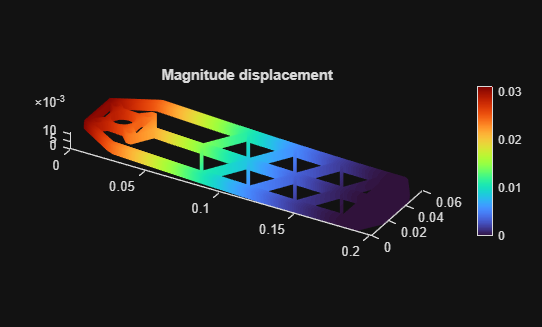

% Data to visualize
meshData = Model_1_result_ASB.Mesh;
nodalData = Model_1_result_ASB.Displacement.Magnitude;
deformationData = Model_1_result_ASB.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",0.1921, ...
    "Title","Magnitude displacement", ...
    "ColorLimits",[0 0.03123]);


% Clear temporary variables
clearvars meshData nodalData deformationData
